#### Learning Rates

- 3 channels

- 9 denoising steps

- 0 seed

- beta coeff (use expert dataset)

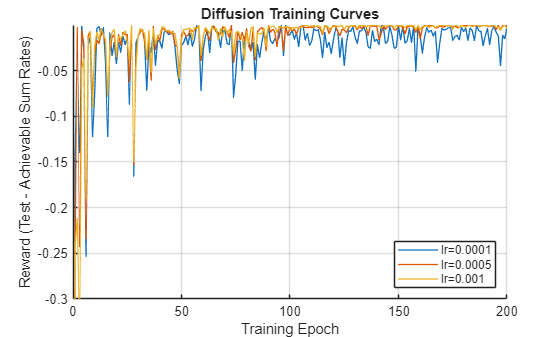

% Define file paths
paths = {
    'C:\Users\inula\Downloads\default_diffusion_Jul15-112136.csv', % For 0.0001
    'C:\Users\inula\Downloads\default_diffusion_Jul15-112500.csv', % For 0.0005
    'C:\Users\inula\Downloads\default_diffusion_Jul15-112841.csv'  % For 0.001
};

% Optional: labels for legend
labels = {'lr=0.0001', 'lr=0.0005', 'lr=0.001'};

figure; hold on;

for i = 1:3
    path = paths{i};  % Use curly braces to index cell array
    data = readmatrix(path);  % Read CSV into a matrix
    
    % Assume 2 columns: x and y
    plot(data(:,2)/10, data(:,3), 'LineWidth', 1);  % Plot each line
end

xlabel('Training Epoch');
ylabel('Reward (Test - Achievable Sum Rates)');
legend(labels, Location="southeast");
title('Diffusion Training Curves');
ylim([-0.3 inf]);
xlim([0 200]);
grid on;

#### Random Seed

- 3 channels

- 9 denoising steps

- lr = 0.0005

- beta coeff (use expert dataset)

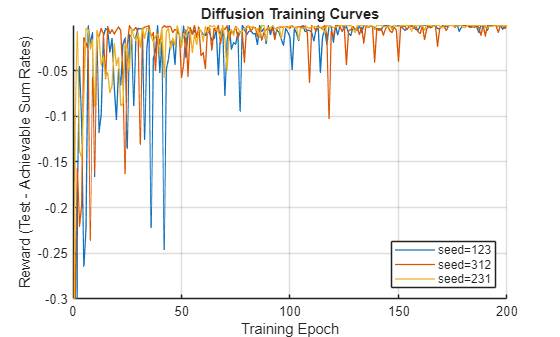

% Define file paths
paths = {
    'C:\Users\inula\Downloads\log_default_diffusion_Jul17-125939.csv', % For 123
    'C:\Users\inula\Downloads\log_default_diffusion_Jul17-130641.csv', % For 312
    'C:\Users\inula\Downloads\log_default_diffusion_Jul17-130843.csv'  % For 231
};

% Optional: labels for legend
labels = {'seed=123', 'seed=312', 'seed=231'};

figure; hold on;

for i = 1:3
    path = paths{i};  % Use curly braces to index cell array
    data = readmatrix(path);  % Read CSV into a matrix
    
    % Assume 2 columns: x and y
    plot(data(:,2)/10, data(:,3), 'LineWidth', 1);  % Plot each line
end

xlabel('Training Epoch');
ylabel('Reward (Test - Achievable Sum Rates)');
legend(labels, Location="southeast");
title('Diffusion Training Curves');
ylim([-0.3 inf]);
xlim([0 200]);
grid on;

#### Denoising Steps

- 3 channels

- lr = 0.0005

- 0 seed

- beta coeff (use expert dataset)

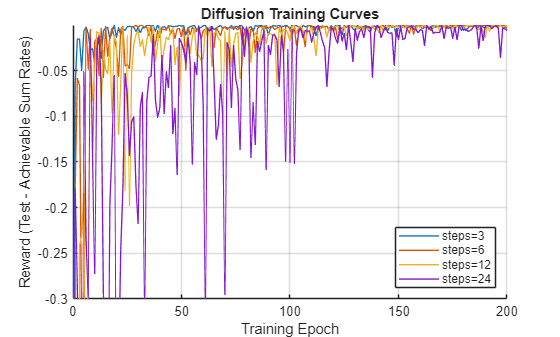

% Define file paths
paths = {
    'C:\Users\inula\Downloads\log_default_diffusion_Jul17-131636.csv', % For 3
    'C:\Users\inula\Downloads\log_default_diffusion_Jul17-132057.csv', % For 6
    'C:\Users\inula\Downloads\log_default_diffusion_Jul17-132510.csv', % For 12
    'C:\Users\inula\Downloads\log_default_diffusion_Jul17-132755.csv'  % For 24
};

% Optional: labels for legend
labels = {'steps=3', 'steps=6', 'steps=12', 'steps=24'};

figure; hold on;

for i = 1:4
    path = paths{i};  % Use curly braces to index cell array
    data = readmatrix(path);  % Read CSV into a matrix
    
    % Assume 2 columns: x and y
    plot(data(:,2)/10, data(:,3), 'LineWidth', 1);  % Plot each line
end

xlabel('Training Epoch');
ylabel('Reward (Test - Achievable Sum Rates)');
legend(labels, Location="southeast");
title('Diffusion Training Curves');
ylim([-0.3 inf]);
xlim([0 200]);
grid on;

#### Expert Dataset

- 3 channels

- 9 denoising steps

- lr = 0.0005

- 0 seed

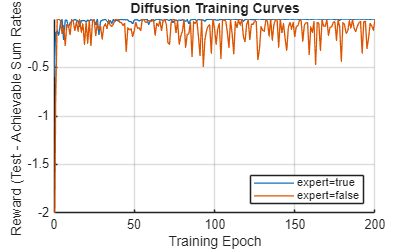

% Define file paths
paths = {
    'C:\Users\inula\Downloads\log_default_diffusion_Jul17-133858.csv', % beta coeff
    'C:\Users\inula\Downloads\log_default_diffusion_Jul17-134501.csv', % no beta coeff
};

% Optional: labels for legend
labels = {'expert=true', 'expert=false'};

figure; hold on;

for i = 1:2
    path = paths{i};  % Use curly braces to index cell array
    data = readmatrix(path);  % Read CSV into a matrix
    
    % Assume 2 columns: x and y
    plot(data(:,2)/10, data(:,3), 'LineWidth', 1);  % Plot each line
end

xlabel('Training Epoch');
ylabel('Reward (Test - Achievable Sum Rates)');
legend(labels, Location="southeast");
title('Diffusion Training Curves');
ylim([-2 inf]);
xlim([0 200]);
grid on;